
% Code to extract data from csv file into seprate folder by labels

%       UNCOMMENT /COMMENT THIS SECTION AS WE NEED TO USE ONLY ONE TIME IN
%       BEGINNING  OR DON'T RUN THIS SECTION AGAIN AND AGAIN extracting data from the CSV file code 
%%---------------------------------------------------------------------------  




% for j = 1:6
%     cat  = solution.category == j %assigning the category label 
%     cat1 = solution(cat ,'id') %% accessing id
%    %    [row2, col2] = find(solution == '2')
%    cat1_array = cat1.id %% converting the table into array to ease of access in matlab
%   
% 
%    i = 1;
%    while i<size(cat1_array,1)
%         x = cat1_array(i,1);
%         
% %adding numeric and string in matlab dir = x + ".png"
% 
%         movefile(x + ".png" , 'j','f'); %%move the image to specified label folder already made by me
%                                         %%f for force writing over so if some problem occurs     
%         i = i + 1;
%    end
% end      
        
%---------------------------------------------------------------------------



nnet = googlenet; %%load the googlenet .
% analyzeNetwork(nnet);

% load the training images intoa imagedatastore
trainimg = imageDatastore('C:\Users\Lenovo\Desktop\pan iit hackathon\training_2\training\','IncludeSubfolders',true,'LabelSource', 'foldernames')

trainimg =   ImageDatastore with properties:

                       Files: {
                              ' ...\Users\Lenovo\Desktop\pan iit hackathon\training_2\training\1\1002.png';
                              ' ...\Users\Lenovo\Desktop\pan iit hackathon\training_2\training\1\1014.png';
                              ' ...\Users\Lenovo\Desktop\pan iit hackathon\training_2\training\1\1025.png'
                               ... and 4997 more
                              }
                      Labels: [1; 1; 1 ... and 4997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


numClasses = numel(categories(trainimg.Labels));  % no of labels

% GET THE INPUT SIZE INTO FIRST LAYER
layers = nnet.Layers; 
inlayer = layers(1)

inlayer =   ImageInputLayer with properties:

                Name: 'data'
           InputSize: [224 224 3]

   Hyperparameters
    DataAugmentation: 'none'
       Normalization: 'zerocenter'
        AverageImage: [224×224×3 single]


insize = inlayer.InputSize

insize =    224   224     3


%THIS PART OF CODE IS NOT PART OF FINAL CODE , THIS IS JUST FOR TESTING THE
%DATA TRAINED EFFICENCY BY OURSELVES

%--------------------------------------------------------------------------------------
% % % % [trainimg ,testimg] = splitEachLabel(imds,750);
% % % % Augmenter = imageDataAugmenter( 'RandRotation',[-50,50],'RandYShear',[0 45]);
% % 
% % %%'RandXTranslation',[-3 3],'RandYTranslation',[-3 3],'RandXReflection',true,'RandYReflection',true,'RandXScale',[0.5 1],'RandYScale',[0.5 3],'RandXShear',[0 40]
%---------------------------------------------------------------------------------------


% [trainImgs,testImgs] = splitEachLabel(auds,750);
%%replacing layers
if isa(nnet,'SeriesNetwork') 
  lgraph = layerGraph(layers); 
else
  lgraph = layerGraph(nnet);
end 

[learnableLayer,classLayer] = findLayersToReplace(lgraph) %% FINDLAYERS TO REPLACE IS A DEFINED FUNCTION ,ATTACHED.

learnableLayer =   FullyConnectedLayer with properties:

          Name: 'loss3-classifier'

   Hyperparameters
     InputSize: 1024
    OutputSize: 1000

   Learnable Parameters
       Weights: [1000×1024 single]
          Bias: [1000×1 single]

  Show all properties


classLayer =   ClassificationOutputLayer with properties:

            Name: 'output'
         Classes: [1000×1 categorical]
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'


[learnableLayer,classLayer]  % watch out which layers you are replacing 

ans =   1x2 Layer array with layers:

     1   'loss3-classifier'   Fully Connected         1000 fully connected layer
     2   'output'             Classification Output   crossentropyex with 'tench' and 999 other classes

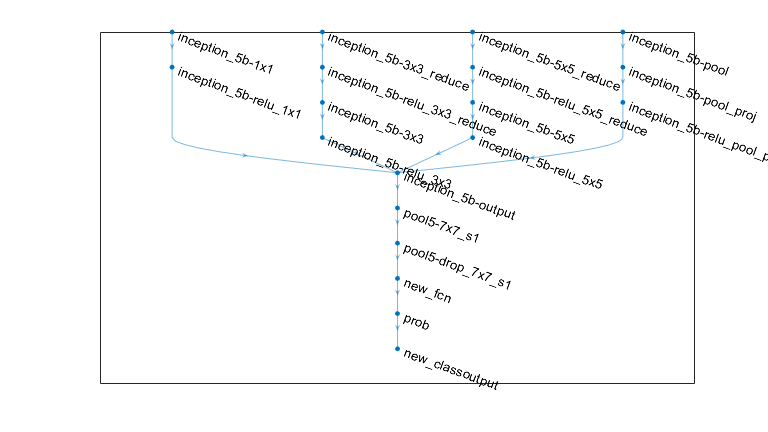



%% replace layer specified according to the type : FullyConnectedLayer or Convolution2DLayer 
if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses,'Name','new_fcn','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, 'Name','new_conv','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer); %% replace the layers with new learned layers

newClassLayer = classificationLayer('Name','new_classoutput'); %% give the name as new_classoutput
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);  

%plot the graph of connected layers  to see if they are connected. 
figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

%freeze initial weights  
layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);

%%data & image augmentation
pixelRange = [-30 30];
scaleRange = [0.9 1.1];
% imageAugmenter = imageDataAugmenter('RandXReflection',true,'RandXTranslation',pixelRange, 'RandXScale',scaleRange,'RandYScale',scaleRange,'RandRotation',[-30 30],'RandXShear',[0 20],'RandYShear',[0 20]);
imageAugmenter = imageDataAugmenter('RandXReflection',true, 'RandXTranslation',pixelRange,'RandXScale',scaleRange,'RandYScale',scaleRange,'RandRotation',[-30 30]);
atrainimg  = augmentedImageDatastore([224 224 3],trainimg, 'DataAugmentation',imageAugmenter);




options = trainingOptions('sgdm','InitialLearnRate', 0.001); %% 'name', value pairs value of alpha , the learning rate


options = trainingOptions('sgdm','MaxEpochs',12 ,'MiniBatchSize',10,'InitialLearnRate',0.001, 'Shuffle','every-epoch','Verbose',true,'Plots','training-progress');

trained_net = trainNetwork(atrainimg, lgraph, options) %% trainNetwork takes the lgraph and options  

Training on single GPU.


Initializing image normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       10.00% |       1.9992 |          0.0015 |
|       1 |          50 |       00:00:23 |       20.00% |       1.7972 |          0.0015 |
|       1 |         100 |       00:00:45 |       20.00% |       1.7818 |          0.0015 |
|       1 |         150 |       00:01:08 |       30.00% |       1.7694 |          0.0015 |
|       1 |         200 |       00:01:31 |       40.00% |       1.7692 |          0.0015 |
|       1 |         250 |       00:01:54 |       10.00% |       1.7988 |          0.0015 |
|       1 |         300 |       00:02:18 |       40.00% 

trained_net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]


%-----------------------------------------------
% this is a part of code used for testing our trained model and hence NOT A PART OF MAIN CODE


% testpreds = classify(trained_net,testImgs)
% % plot(info.TrainingLoss)
% % 
% % grid on
% % atestimg = augmentedImageDatastore([224 224 3], testimg)
% % [test_prediction ,probs] = classify(trained_net,atestimg)

% figure
% for i = 1:numel(test_prediction)
%     subplot(2,2,i)
%     I = readimage(testimg,test_pediction(i));
%     label = test_prediction(i);
%     imshow(I)
%     title(char(label))
% end

% % atestimg_actual = testimg.Labels
% % numCorrect = nnz(test_prediction == atestimg_actual)
% % fraccorrect = numCorrect/numel(test_prediction)
% % confusionchart(testimg.Labels , test_prediction)

%---------------------------------------------------------

%-------------------------------------------------------------------------
% % THIS CODE MAKE SURE THAT THE IMAGES GO IN ASCENDING ORDER OF FILENAME, 
%    USED A CODE TO ENSURE IT THAT THE OUTPUT IS ALSO IN THE FORM 
%    OF A ARRAY WHICH CORRESPONDS ARRAY(i) = LABEL OF ith IMAGE NAME.

D = 'C:\Users\Lenovo\Desktop\pan iit hackathon\testing.40k\testing\';

S = dir(fullfile(D,'*.png'))

S = 40000×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


N = natsortfiles({S.name})

N = 1×40000 cell array
  Columns 1 through 673

    {'1.png'}    {'2.png'}    {'3.png'}    {'4.png'}    {'5.png'}    {'6.png'}    {'7.png'}    {'8.png'}    {'9.png'}    {'10.png'}    {'11.png'}    {'12.png'}    {'13.png'}    {'14.png'}    {'15.png'}    {'16.png'}    {'17.png'}    {'18.png'}    {'19.png'}    {'20.png'}    {'21.png'}    {'22.png'}    {'23.png'}    {'24.png'}    {'25.png'}    {'26.png'}    {'27.png'}    {'28.png'}    {'29.png'}    {'30.png'}    {'31.png'}    {'32.png'}    {'33.png'}    {'34.png'}    {'35.png'}    {'36.png'}    {'37.png'}    {'38.png'}    {'39.png'}    {'40.png'}    {'41.png'}    {'42.png'}    {'43.png'}    {'44.png'}    {'45.png'}    {'46.png'}    {'47.png'}    {'48.png'}    {'49.png'}    {'50.png'}    {'51.png'}    {'52.png'}    {'53.png'}    {'54.png'}    {'55.png'}    {'56.png'}    {'57.png'}    {'58.png'}    {'59.png'}    {'60.png'}    {'61.png'}    {'62.png'}    {'63.png'}    {'64.png'}    {'65.png'}    {'66.png'}    {'67.png'}    {'68.png'}    {'69.


F = cellfun(@(n)fullfile(D,n),N,'uni',0)
F = F'




%---------------------------------------------

% GET THE PREDICTION OUTPUT

pimds =  imageDatastore(F)
apimds = augmentedImageDatastore([224 224 3], pimds)
preds_out = classify(trained_net,apimds)

%%%% STORED INTO A CSV FILE MANUALLY